EN3551: DIGITAL SIGNAL PROCESSING

Assignment 1: Detecting Harmonics in Noisy Data and Signal Interpolation using DFT

Index Number : 200377M

The test signal in this part of the experiment is the first 20,000 samples of a music clip

”Hallelujah” by Handel, which is available from MATLAB. To get it, execute ‘load handel’

in MATLAB. Let us denote the loaded signal as y[n]

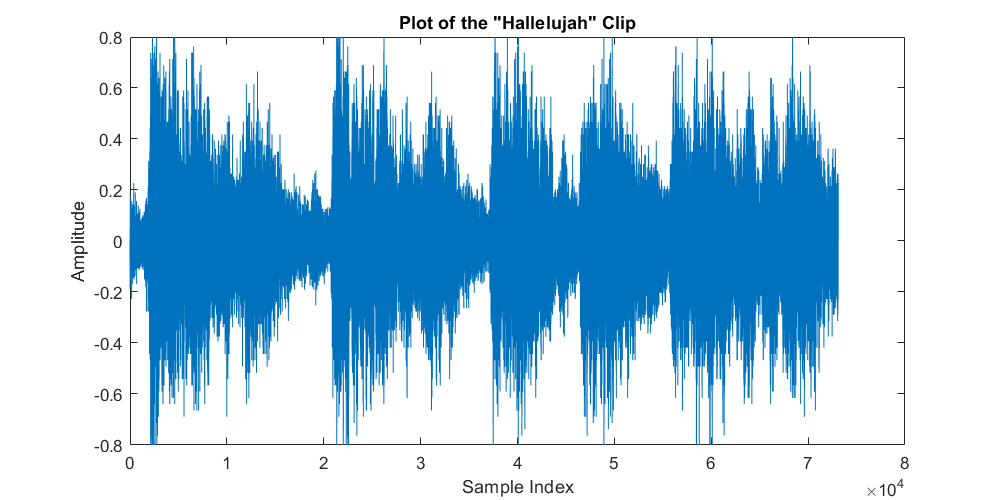

% Load the 'Hallelujah' music clip
load handel;

% To plot the signal:
figure('Position', [100,100,800,400])
plot(y);
title('Plot of the "Hallelujah" Clip');
xlabel('Sample Index');
ylabel('Amplitude');

The signals to be used below are generated from the first 20,000 samples of y[n] as follows:

% Define the signal length
N = 20000;  % First 20,000 samples

% Create signals x, x2, x3, and x4
x = y(1:N);
x2 = x(1:2:N);  % Odd
x3 = x(1:3:N);  % Odd
x4 = x(1:4:N);  % Even

Apply the DFT-based method to interpolate the signals x2, x3 and x4 (note whether they

are odd or even) and make some comparisons as follows:

Interpolate the signal x2 with K = 1. Compute the difference between the interpo�lated signal and the original signal x in 2-norm (notice that the length of the two

signals involved might be different). Compare the waveform of the interpolated sig�nal with that of the original signal x by plotting the first 50 samples of both signals

in the same figure.

% Interpolate x2 with K = 1
K = 1;

% Compute the Discrete Fourier Transform (DFT) of x2
DFT_x2 = fft(x2);
N = length(x2);

% Check if N is even
if mod(N, 2) == 0  
    % N is even
    N2 = N / 2;
    % Apply zero padding and interpolation
    DFT_x2_interp = [DFT_x2(1:N2); DFT_x2(N2 + 1) / 2; zeros((K * N) - 1, 1); DFT_x2(N2 + 1) / 2; DFT_x2((N2 + 2):N)];
else
    % N is odd
    N1 = (N + 1) / 2;
    % Apply zero padding and interpolation
    DFT_x2_interp = [DFT_x2(1:N1); zeros(K * N, 1); DFT_x2((N1 + 1):N)];
end

% Inverse FFT to get the interpolated signal
x2_interp = (K + 1) * ifft(DFT_x2_interp);

% Extract the relevant part of the interpolated signal
x2_interp_extracted = x2_interp(1:((K + 1) * (N - 1)) + 1);

% Compute the norm difference between the interpolated and original signal
Norm_Difference_x2 = norm(x2_interp_extracted) - norm(x2);
disp(Norm_Difference_x2);

    7.6732



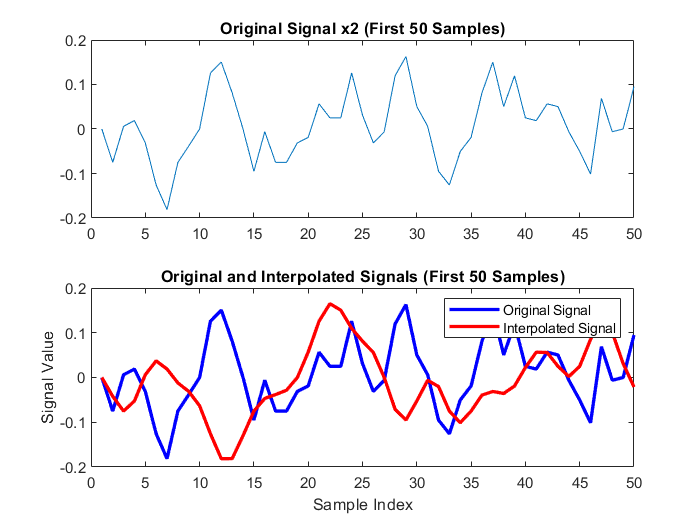


%plot Plot the original and interpolated signals
figure;
subplot(2, 1, 1); plot(x2(1:50)); title('Original Signal x2 (First 50 Samples)');
subplot(2, 1, 2); plot(x2_interp_extracted(1:50)); title('Interpolated Signal x2 (First 50 Samples)');

% Plot both signals on the same axes
plot(x2(1:50), 'b', 'LineWidth', 2); % Original signal in blue
hold on;
plot(x2_interp_extracted(1:50), 'r', 'LineWidth', 2); % Interpolated signal in red
hold off;

% Add labels and title
xlabel('Sample Index');
ylabel('Signal Value');
title('Original and Interpolated Signals (First 50 Samples)');
legend('Original Signal', 'Interpolated Signal');

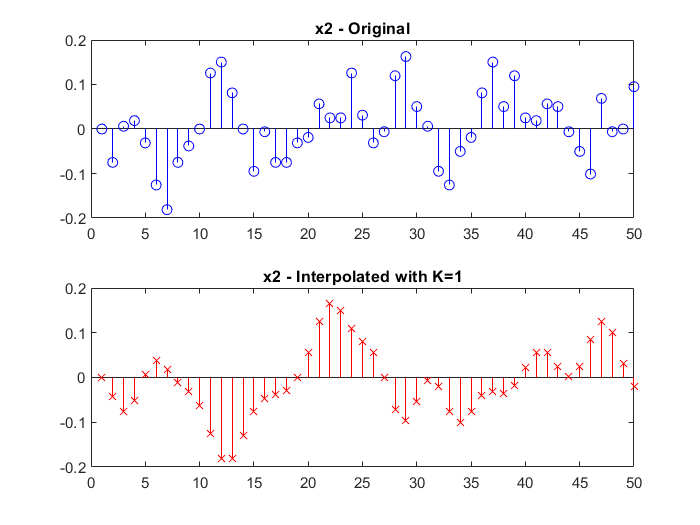


% Plot the original and interpolated signals in stem plot
figure(11);
subplot(2, 1, 1);
stem(x2(1:50), 'b', 'Marker', 'o');
title('x2 - Original');
subplot(2, 1, 2)
stem(x2_interp_extracted(1:50), 'r', 'Marker', 'x');
title('x2 - Interpolated with K=1');

Repeat above for signal x3 with K = 2.

% Interpolate x3 with K=2
K = 2;

% Compute the DFT of x3
DFT_x3 = fft(x3);
N = length(x3);

% Check if N is even
if mod(N, 2) == 0  
    % N is even
    N2 = N / 2;
    % Apply zero padding and interpolation
    DFT_x3_interp = [DFT_x3(1:N2); DFT_x3(N2 + 1) / 2; zeros((K * N) - 1, 1); DFT_x3(N2 + 1) / 2; DFT_x3((N2 + 2):N)];
else
    % N is odd
    N1 = (N + 1) / 2;
    % Apply zero padding and interpolation
    DFT_x3_interp = [DFT_x3(1:N1); zeros(K * N, 1); DFT_x3((N1 + 1):N)];
end

% Inverse FFT to get the interpolated signal
x3_interp = (K + 1) * ifft(DFT_x3_interp);

% Extract the relevant part of the interpolated signal
x3_interp_extracted = x3_interp(1:((K + 1) * (N - 1)) + 1);

% Compute the norm difference between the interpolated and original signal
Norm_Difference_x3 = norm(x3_interp_extracted) - norm(x3);
disp(Norm_Difference_x3);

   11.0927



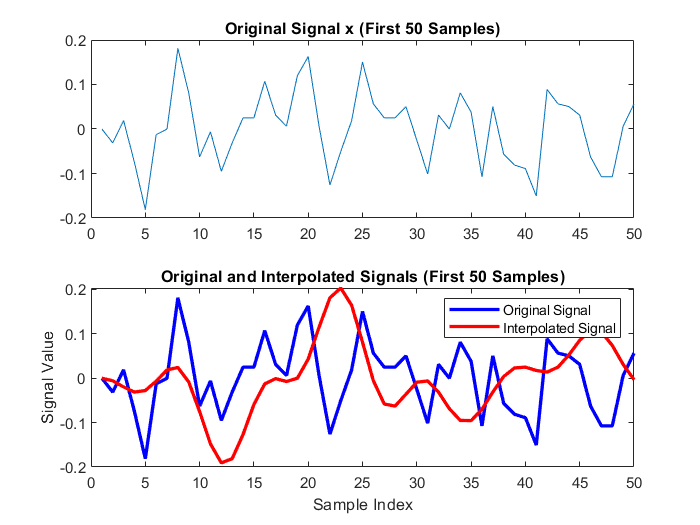

% Plot the first 50 samples of both signals
figure;
subplot(2, 1, 1); plot(x3(1:50)); title('Original Signal x (First 50 Samples)');
subplot(2, 1, 2); plot(x3_interp_extracted(1:50)); title('Interpolated Signal x3 (First 50 Samples)');

% Plot both signals on the same axes
plot(x3(1:50), 'b', 'LineWidth', 2); % Original signal in blue
hold on;
plot(x3_interp_extracted(1:50), 'r', 'LineWidth', 2); % Interpolated signal in red
hold off;

% Add labels and title
xlabel('Sample Index');
ylabel('Signal Value');
title('Original and Interpolated Signals (First 50 Samples)');
legend('Original Signal', 'Interpolated Signal');

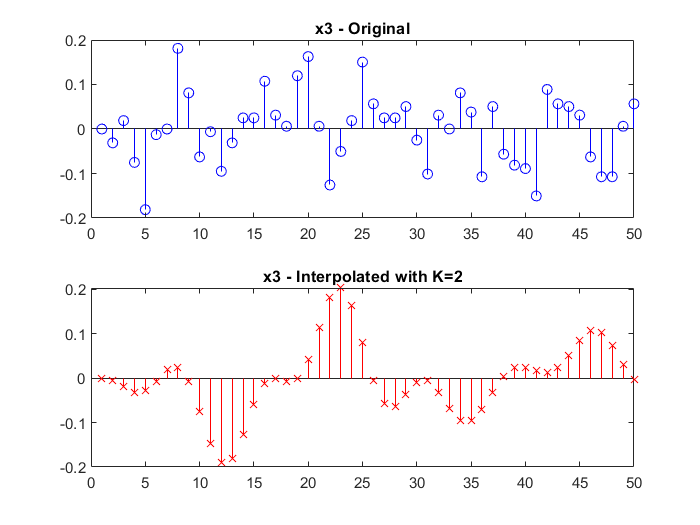

% Plot the original and interpolated signals in stem plot
figure(12);
subplot(2, 1, 1);
stem(x3(1:50), 'b', 'Marker', 'o');
title('x3 - Original');
subplot(2, 1, 2)
stem(x3_interp_extracted(1:50), 'r', 'Marker', 'x');
title('x3 - Interpolated with K=2');

Repeat the first part for signal x4 with K = 3.

% Interpolate x4 with K = 3
K = 3;

% Compute the DFT of x4
DFT_x4 = fft(x4);
N = length(x4);

% Check if N is even
if mod(N, 2) == 0  
    % N is even
    N2 = N / 2;
    % Apply zero padding and interpolation
    DFT_x4_interp = [DFT_x4(1:N2); DFT_x4(N2 + 1) / 2; zeros((K * N) - 1, 1); DFT_x4(N2 + 1) / 2; DFT_x4((N2 + 2):N)];
else
    % N is odd
    N1 = (N + 1) / 2;
    % Apply zero padding and interpolation
    DFT_x4_interp = [DFT_x4(1:N1); zeros(K * N, 1); DFT_x4((N1 + 1):N)];
end

% Inverse FFT to get the interpolated signal
x4_interp = (K + 1) * ifft(DFT_x4_interp);

% Extract the relevant part of the interpolated signal
x4_interp_extracted = x4_interp(1:((K + 1) * (N - 1)) + 1);

% Compute the norm difference between the interpolated and original signal
Norm_Difference_x4 = norm(x4_interp_extracted) - norm(x4);
disp(Norm_Difference_x4);

   13.1210



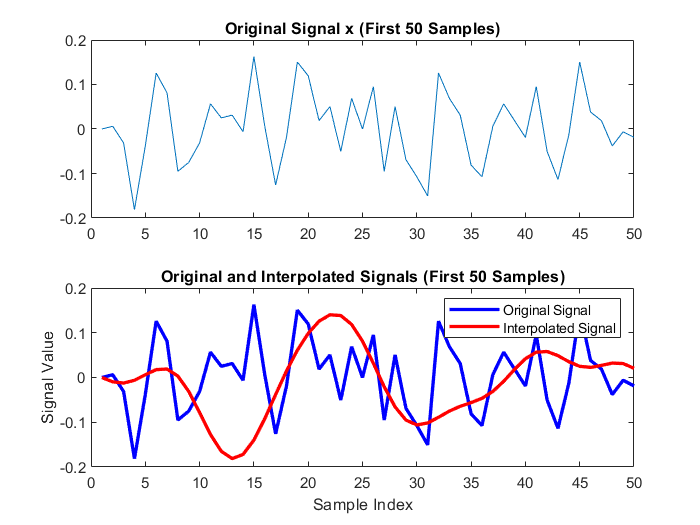


% Plot the first 50 samples of both signals
figure;
subplot(2, 1, 1); plot(x4(1:50)); title('Original Signal x (First 50 Samples)');
subplot(2, 1, 2); plot(x4_interp_extracted(1:50)); title('Interpolated Signal x4 (First 50 Samples)');

% Plot both signals on the same axes
plot(x4(1:50), 'b', 'LineWidth', 2); % Original signal in blue
hold on;
plot(x4_interp_extracted(1:50), 'r', 'LineWidth', 2); % Interpolated signal in red
hold off;

% Add labels and title
xlabel('Sample Index');
ylabel('Signal Value');
title('Original and Interpolated Signals (First 50 Samples)');
legend('Original Signal', 'Interpolated Signal');

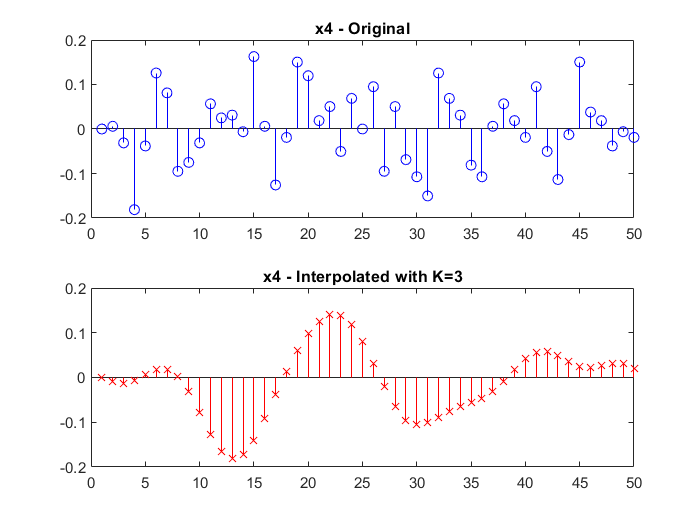


% Plot the original and interpolated signals
figure(13);
subplot(2, 1, 1);
stem(x4(1:50), 'b', 'Marker', 'o');
title('x4 - Original');
subplot(2, 1, 2)
stem(x4_interp_extracted(1:50), 'r', 'Marker', 'x');
title('x4 - Interpolated with K=3');

Observe and comment on the results obtained for each of the above tasks.